1.Use the **eye** function to create a 4 x 5 diagonal matrix called ***A*** with 7’s on the leading diagonal.

A = 7 * eye(4,5);
disp(A);

     7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0



2. Create a 3 x 3 elementary matrix called ***E*** that adds 3 of the 1st row to the 3rd row of a matrix. Test it with a random 3 x 3 matrix of integers.

E = eye(3, 3);
E(3, 1) = 3;
disp(E);

     1     0     0
     0     1     0
     3     0     1



A = randi([1,10], 3,3);
disp(A);

     8     5     6
     5     4     9
     5     6     8



B = E*A;
disp(B);

     8     5     6
     5     4     9
    29    21    26



3. Augment the test matrix from question 2 with a 3 x 3 identity matrix then use Matlab’s **rref** function to find it’s reduced echelon form.

4. Create the coefficient matrix for the following linear system, check that its determinant is not 0, then calculate the solution using the inverse matrix method (*hint:* you can find the inverse of a matrix with the **inv** function).

A = [3, 4; 5, 6];
b = [3; 7];
Ainv = inv(A);
det(inv(A))

ans = -0.5000

result = Ainv*b;
disp(result);

    5.0000
   -3.0000



5. Solve the system above but using Matlab’s left-division operator.

result = A\b;
disp(result);

    5.0000
   -3.0000



6. There are 3 reactors linked by pipes as shown below. The rate of transfer of chemicals through each pipe is equal to a flow rate (Q, with units of cubic meters per ­second) multiplied by the concentration of the reactor from which the flow originates (c, with units of milligrams per cubic meter). If the system is at a steady state, the transfer into each reactor will balance the transfer out. Develop mass-balance equations for the reactors and solve the three simultaneous linear algebraic equations for their concentrations.

Q = [130, -30 0; 90, -90, 0; -40, -60, 120];
b = [500; 0; 500];
result = Q\b;
disp(result);

    5.0000
    5.0000
    8.3333



7. Use Matlab’s **fsolve** function to find the roots of the system. Since there are infinite solutions you do not need to find every root. Just locate and plot those given in the default window. Plotting is always a good idea to give you an idea of how many roots you are looking for and where to make the initial guesses. Use the **fimplicit** function to plot these implicit functions on the same graph. Define a function at the end of your script closed with keyword **end** that holds the system of equations. Advanced users can also use the ginput() function to pick starting initial guesses

f1 = @(x,y) exp(x*y) - y.^2;
f2 = @(x,y) cos(x+y);
fimplicit(f1, [-5, 5, -5, 5]);

hold on;
fimplicit(f2, [-5, 5, -5, 5]);
[x, fx] = fsolve(@nonlin, [-1,-2])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =    -0.3387   -1.2320


fx = 1.0e-07 *

   -0.9755
    0.0000


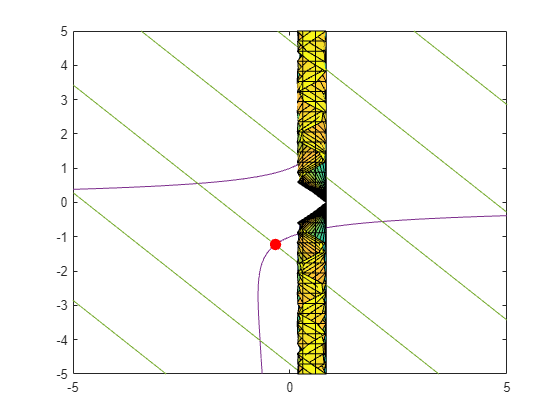

plot(x(1),x(2),'or','MarkerFaceColor','r','MarkerSize',8)
hold off

8. Find a root of the following system. Check your solution.

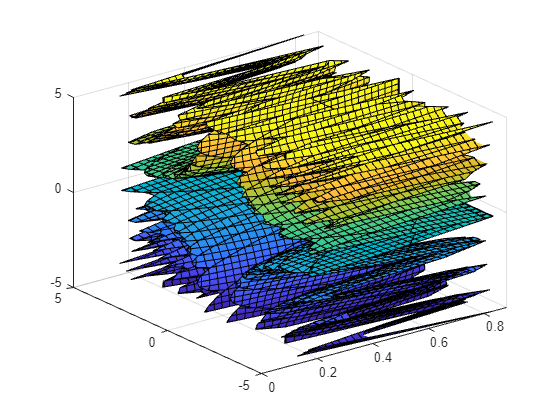

clf reset;
f1 = @(x, y, z) 3*x - cos(y*z) - 3/2;
f2 = @(x, y, z) 4*x.^2 - 625*y.^2 + 2*z - 1;
f3 = @(x, y, z) 20*z + exp(-x*y) + 9;
% p8_a = @(x, y, z) 3*x - cos(y.*z) - (3 / 2);
% p8_b = @(x, y, z) (4 * x.^2) - (625*y.^2) + (2 * z) - 1;
% p8_c = @(x, y, z) (20 * z) + exp(-x * y) + 9;
fimplicit3(f1, [-5, 5, -5, 5, -5, 5])

[x, fx] = fsolve(@nonlin3, [1, 1, 1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     0.8333    0.0353   -0.4985


fx = 1.0e-13 *

   -0.0044
   -0.1044
         0


Function

function f = nonlin(x)
f = [exp(x(1).*x(2)) - x(2).^2; cos(x(1)+x(2))];
% f = [exp(x(1).*x(2))-x(2).^2;cos(x(1)+x(2))];
end
function f = nonlin3(X)
x = X(1);
y = X(2);
z = X(3);
f = [3*x - cos(y*z) - 3/2; 4*x.^2 - 625*y.^2 + 2*z - 1; 20*z + exp(-x*y) + 9];
end